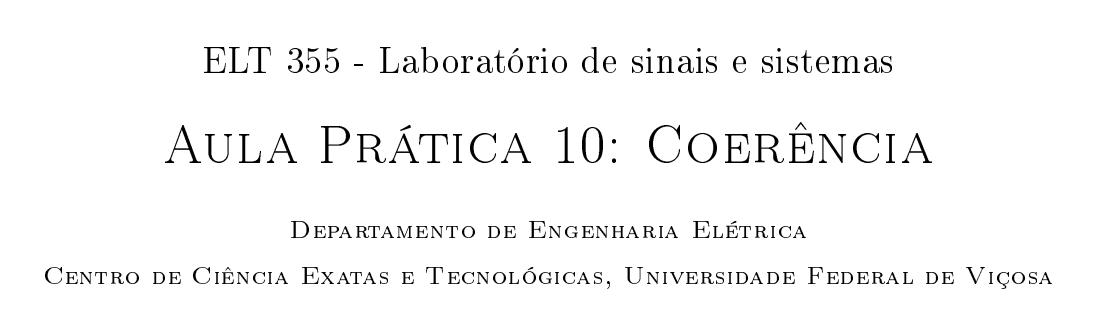

26/05/22

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

## Coerência entre sinais

### Comparando dois sinais sintéticos


$$\hat{\gamma}_{xy}^2 = \frac{ \left| \sum_{i=1}^{M} X_{i}^*  (f) Y_{i} (f) \right|^2}{ \sum_{i=1}^M |X_{i}(f)|^2  \sum_{i=1}^{M} |Y_{i}(f)|^2}$$


Que é a coerência entre os sinais x[n] e y[n], onde M é o número de janelas em que os sinais são medidos. $X_{i}(f)$ e $Y_{i}(f)$são as trasnformadas de Fourier das i-ésimas janelas de cada sinal.

A coerência não mede ou observa a defasagem entre 2 sinais, apenas analisa a similaridade de sua magnitude.

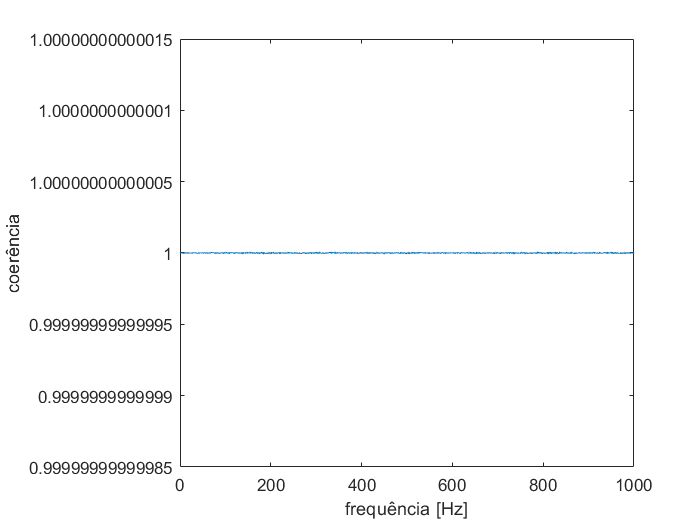

time = [0:0.0005:2];
fs = 1/0.0005;
xa = sin(2*pi*2*time) + 0.5*sin(2*pi*8*time);
xb = sin(2*pi*2*time) + 0.5*sin(2*pi*8*time + (pi/2));

Xa = fft(xa);
Xb = fft(xb);

f = linspace(0, fs/2, length(time)/2);

[coerencia, fc] = mscohere(Xa, Xb, numel(time), 0 , f, fs);
plot(fc, coerencia); xlabel('frequência [Hz]'); ylabel('coerência')

### Diferença WAV e MP3

[x1, f1] = audioread('bird.wav');

x1 =     0.0609
   -0.0094
   -0.0650
   -0.1151
   -0.1590
   -0.1773
   -0.1782
   -0.1831
   -0.1833
   -0.1789


f1 = 44100

[x2, f2] = audioread('bird.wav');

x2 =     0.0609
   -0.0094
   -0.0650
   -0.1151
   -0.1590
   -0.1773
   -0.1782
   -0.1831
   -0.1833
   -0.1789


f2 = 44100


sound(x1, f1)
